signal = sin(2*pi*0.055*(0:1000-1)');
signalSource = dsp.SignalSource(signal,SamplesPerFrame=100,...
    SignalEndAction="Cyclic repetition");
scope = timescope(YLimits=[-2 2],Title="Information bearing signal")

scope =   timescope with properties:

               SampleRate: 1
           TimeSpanSource: 'auto'
    TimeSpanOverrunAction: 'scroll'
                 PlotType: 'line'
              AxesScaling: 'manual'

  Show all properties


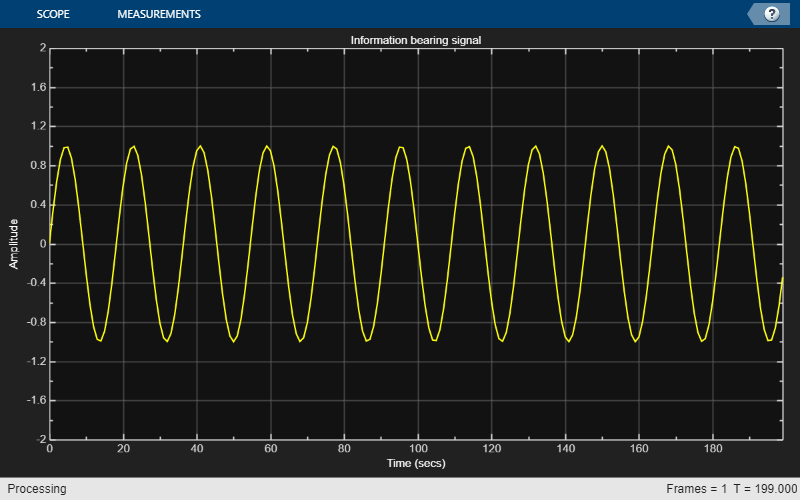

scope(signal(1:200));

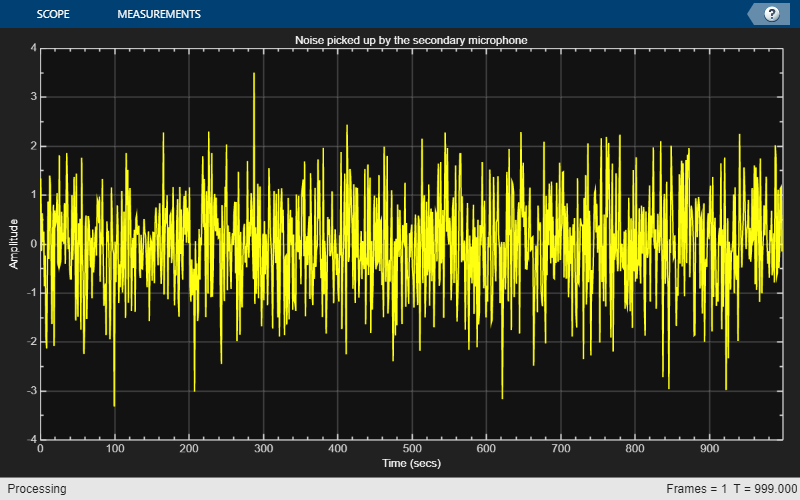

nvar  = 1.0;                  % Noise variance
noise = randn(1000,1)*nvar;   % White noise
noiseSource = dsp.SignalSource(noise,SamplesPerFrame=100,...
    SignalEndAction="Cyclic repetition");
scope = timescope(YLimits=[-4 4], Title="Noise picked up by the secondary microphone");
scope(noise);

lp = dsp.FIRFilter('Numerator',fir1(31,0.5));% Low pass FIR filter

M      = 32;                 % Filter order
delta  = 0.1;                % Initial input covariance estimate
P0     = (1/delta)*eye(M,M); % Initial setting for the P matrix
rlsfilt = dsp.RLSFilter(M,InitialInverseCovariance=P0);

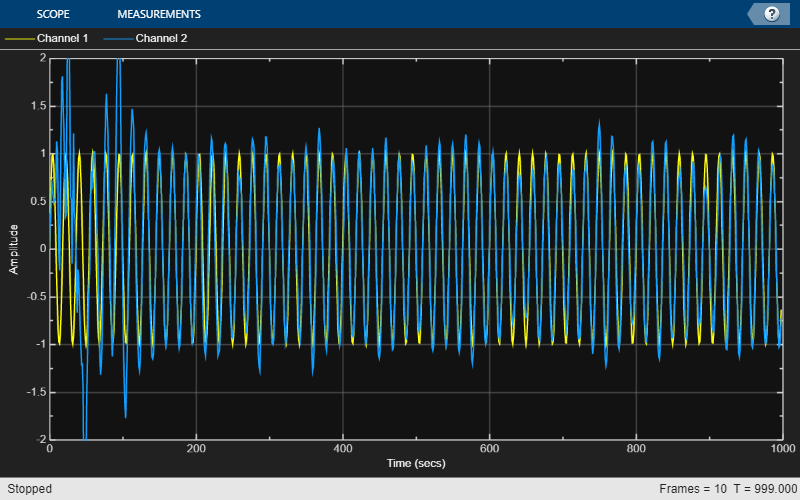

scope = timescope(TimeSpan=1000,YLimits=[-2,2], ...
	              TimeSpanOverrunAction="scroll");
for k = 1:10
    n = noiseSource(); % Noise
    s = signalSource();
    d = lp(n) + s;
    [y,e]  = rlsfilt(n,d);
    scope([s,e]);
end
release(scope);

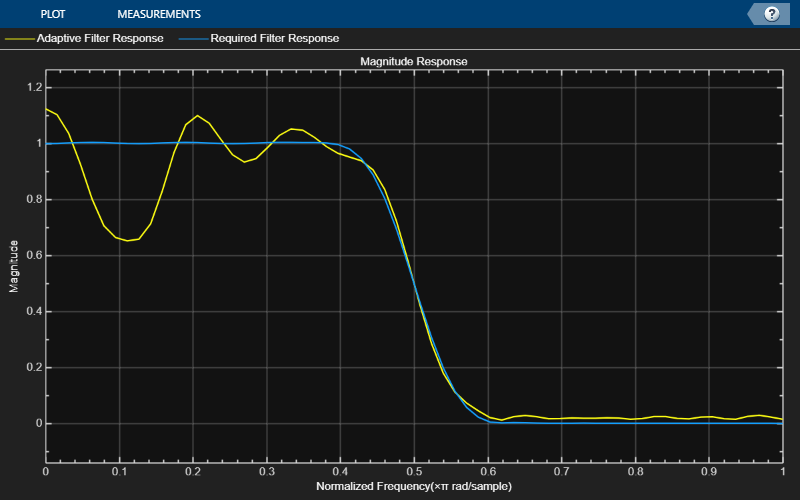

visualizer = dsp.DynamicFilterVisualizer(64,NormalizedFrequency=true,...
    MagnitudeDisplay="Magnitude", ...
    FilterNames=["Adaptive Filter Response","Required Filter Response"]);
visualizer(rlsfilt.Coefficients,1,lp.Numerator,1);